%load images and labels
crop_size = 64;
[test, train, test_labels, train_labels, test_names, train_names] = load_images(crop_size);

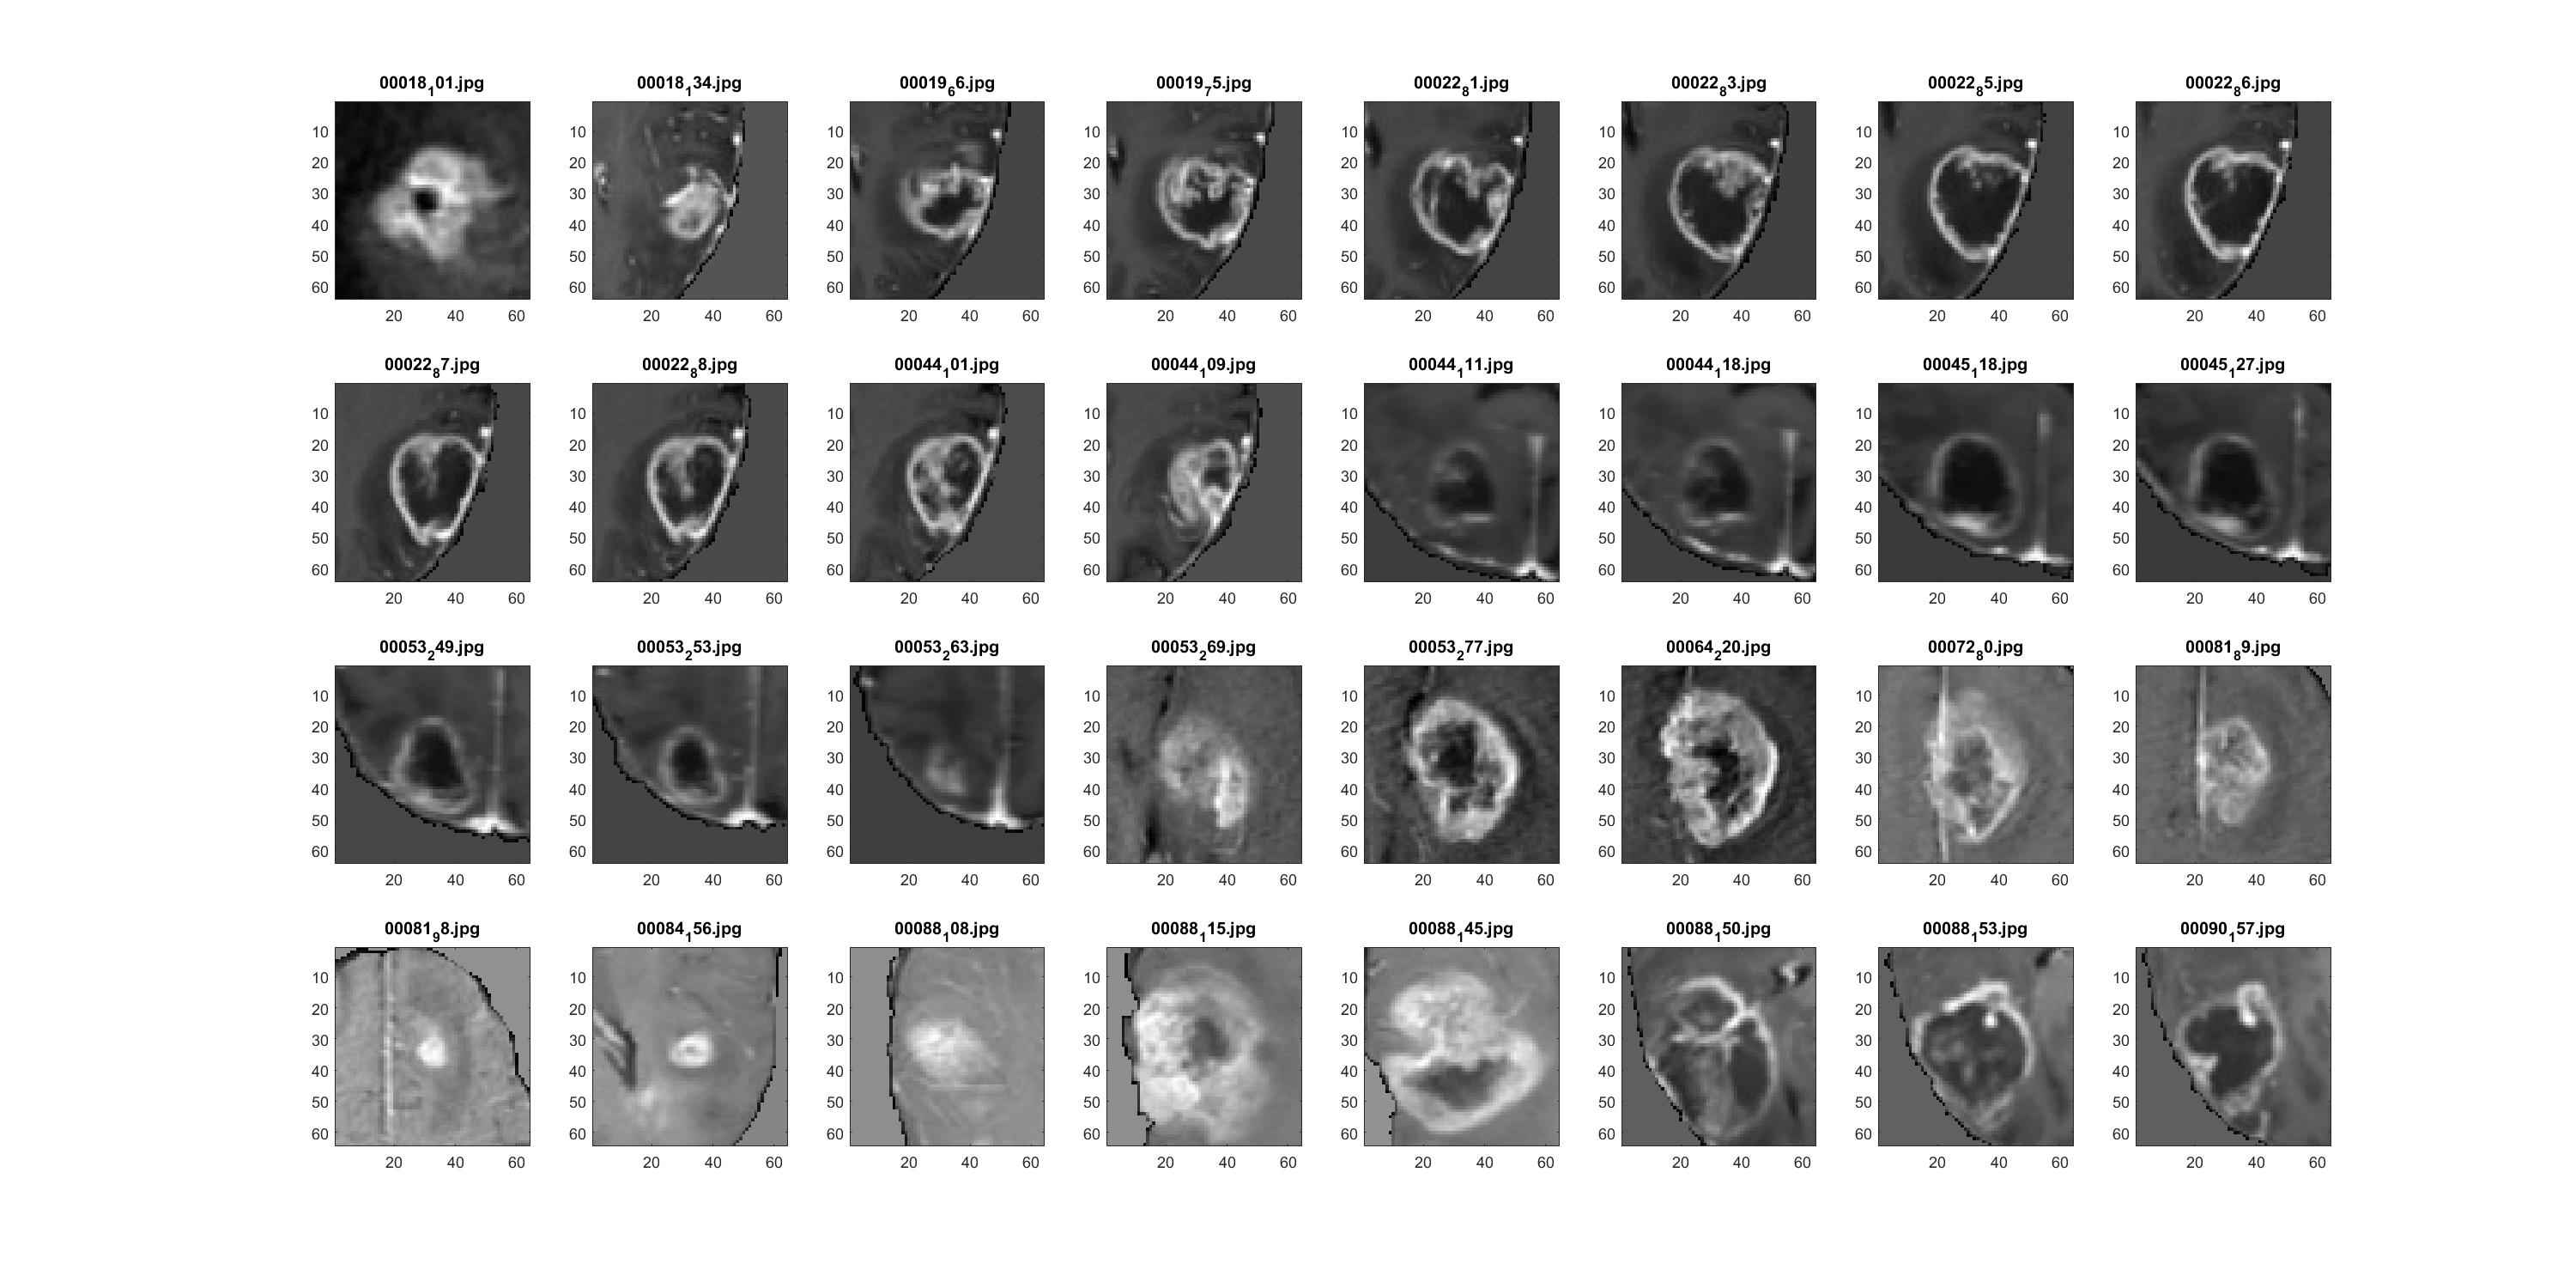

%plot some of the train images
figure(1)
clf
set(figure(1), "Position", [0 0 2000 1000])
 for i=1:32
     subplot(4,8,i)
     imagesc(reshape(train(i,:), 64, 64))
     title(test_names{i})
     
 end
 colormap 'gray'

%PCA to compute tumor-space
 train_mc = train - mean(train, 2);
 R = train_mc' * train_mc;
 [V, D] = eigs(R, 50);

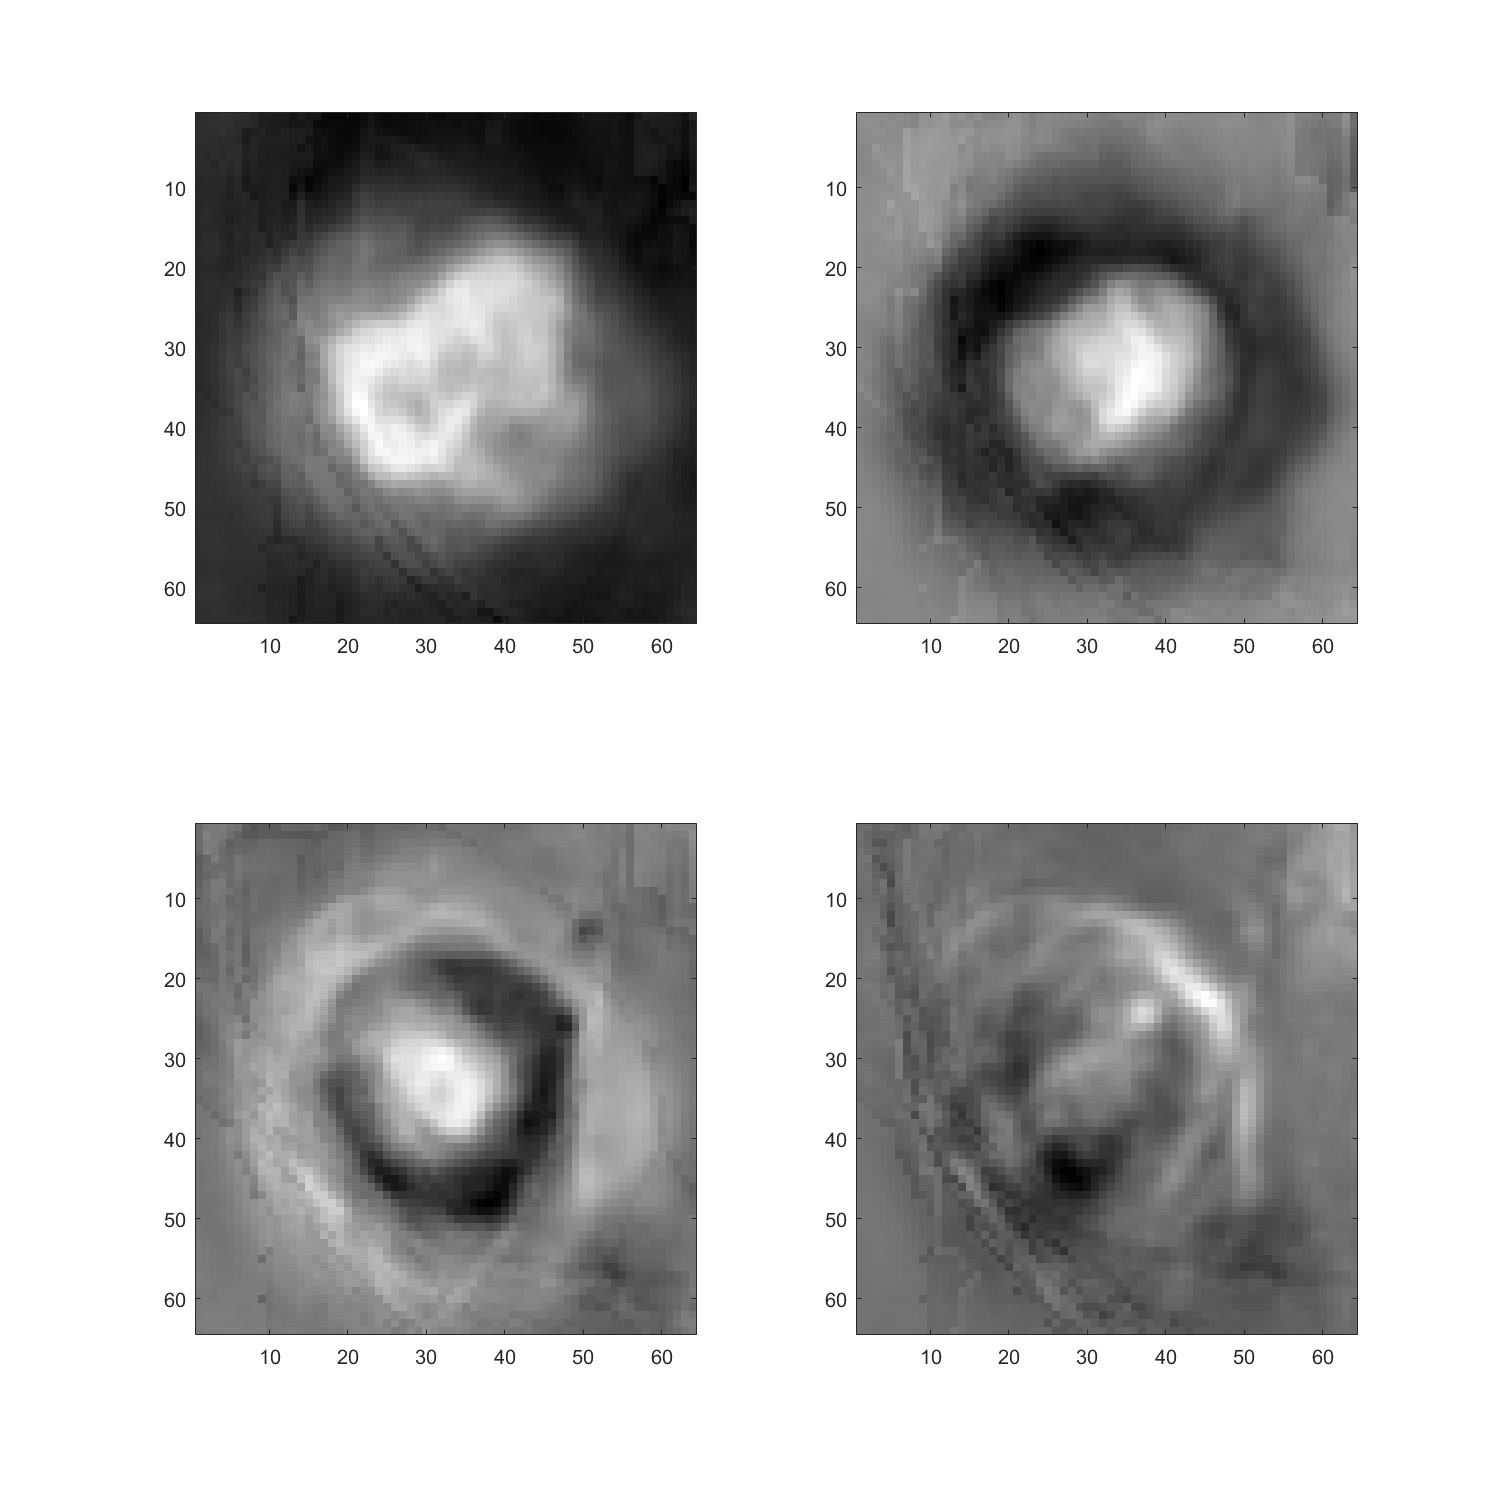

%plot first few eigen-tumors of the tumor space
 figure(2)
 clf
set(figure(2), "Position", [0 0 1000 1000])
 for i=1:4
     subplot(2,2,i)
     imagesc(reshape(V(:,i), crop_size, crop_size))
     %axis equal
 end
 colormap 'gray'

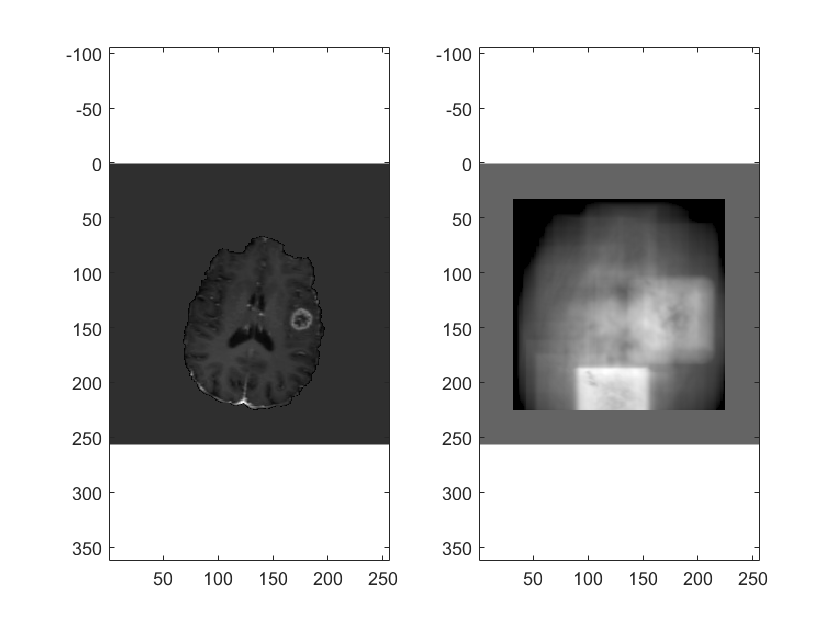

heat_map = zeros(256-crop_size, 256-crop_size);

k = 13;
wholeimage = test(k,:);
wholeimage = reshape(wholeimage, 256, 256);

% wholeimage = double(imread("axial_t1wce_2_class\images\train\00097_72.jpg"));
% img = reshape(wholeimage, 1, []);
% i1 = img < 10;
% i2 = img >= 10;
% img(i1) = mean(img(i2));
% 
% wholeimage = reshape(img, 256, 256);


%loop through all pixels
for i=1:256 - crop_size + 1
        for j=1:256 - crop_size + 1
        
        %isolate 64x64 subimage
        subimage = wholeimage(i:crop_size-1+i, j:crop_size-1+j);
        subimage = reshape(subimage, 1, []);
        %mean center it
        subimage = subimage - mean(subimage);
        
        %project onto tumor-space
        si_comp = subimage * V;
        %reconstruct
        si_restr  = si_comp * V';
        %calculate distance
        epsilon = norm(si_restr - subimage);
        %save value as pixel in heatmap
        heat_map(i, j) = epsilon;
        end
end

%add border to heatmap for pixels with no subimage
heat_map = add_border(heat_map, crop_size);

%plot
figure(9)
clf
subplot(1,2,1)
imagesc(wholeimage)
axis equal
subplot(1,2,2)
imagesc(heat_map)
axis equal
colormap 'gray'

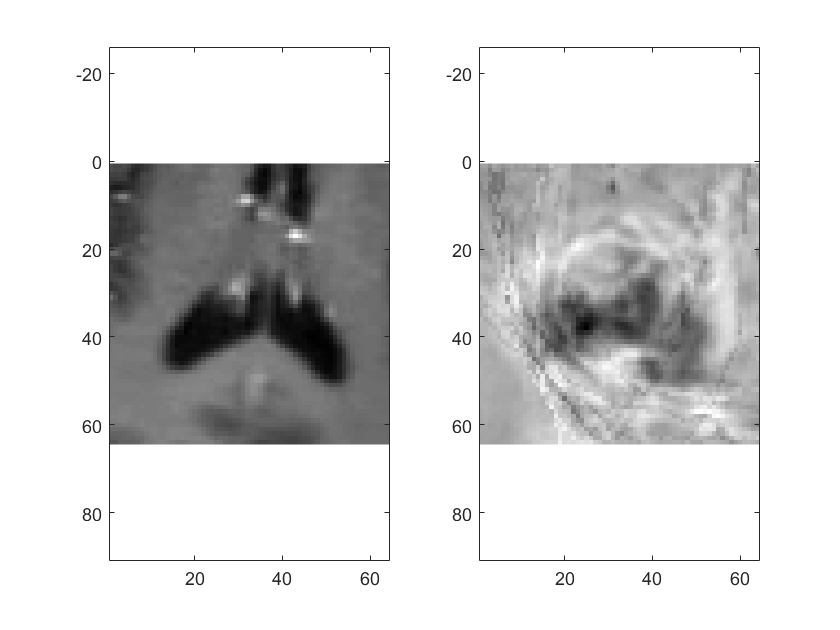

%comparison of what is happening in a single subimage in the heatmap algorithm
k = 13;
img = test(k,:);
i1 = img < 10;
i2 = img >= 10;
img(i1) = mean(img(i2));
img = img- mean(img);
    
    
img = crop_img(reshape(img, 256, 256), [0.5 0.6], crop_size);
img = reshape(img, 1, []);

img_comp = img * V;
img_res = img_comp * V';

%plot
figure(5)
clf
subplot(1,2,1)
imagesc(reshape(img, crop_size, crop_size))
axis equal
subplot(1,2,2)
imagesc(reshape(img_res, crop_size, crop_size))
colormap 'gray'
axis equal


norm(img-img_res)

ans = 750.2736